# Linear Control Design II - Group Work Problem Module 8 Solution

## Description

**Problem 1** Solve Problem 2.10 from the textbook.

**Solution:**

From the problem text four heat power equations are given:


$$q_c = k_c(T_s-T_a) \\ q_g = k_g(T_s-T_g)  \\ q_r = k_r(T_s^4-T_a^4) \\ q = ku $$
            

Remember that all temperatures are absolute temperatures.

**1.1 Nonlinear model and state space model**

The total heat capacity of the oven air space and the product are denoted by $C_s$ and $C_g$ respectively. The expressions for the time derivatives of the temperatures of the different parts of the system can be written as: the change of heat = heat in - heat out.

For the oven the heat balance can be written as:


$$C_s\frac{dT_s}{dt} = q-q_c-q_g-q_r$$


whereas for the product the heat balance can be written as: 


$$C_g\frac{T_g}{dt} = q_g$$


$T_s$ and $T_g$ are chosen as state variables:  $x=\left[\matrix{x_1 \cr x_2}\right]$ = $\left[\matrix{T_s \cr T_g }\right]$. $T_a$ is considered as a disturbance and is called $v$. The system input is $u$. The state space model can now be written as: 

                $\mathbf{\dot{x}} = \left[\matrix {\frac{1}{C_s}(ku-k_c(x_1-v)-k_g(x_1-x_2)-k_r(x_1^4-v^4)) \cr \frac{1}{C_g}k_g(x_1-x_2)}\right]$ = $\left[\matrix {\frac{1}{C_s}((-k_c-k_g)x_1-k_rx_1^4+k_gx_2) \cr \frac{1}{C_g}k_g(x_1-x_2)} \right]$+$\left[\matrix {\frac{1}{C_s}k \cr 0} \right]u$+ $\left[\matrix {\frac{1}{C_s}(k_cv+k_rv^4) \cr 0} \right]$                              


$$y=\left[\matrix {0  &1} \right]\mathbf{x}$$


**1.2 Stationary state	 **    

All time derivatives in $C_s\frac{dT_s}{dt}$ and $C_g\frac{T_g}{dt}$  are set equal to zero and the equations are solved for the state vector $\mathbf{x}$ and the control input $u$

 
$$	0 = q-q_c-q_r-q_g \\
	0 = q_gu$$


This leds to:

	
$$T_{s0} = T_{g0} \\ 0 = q-q_c-q_r \leftrightarrow  \\ q = q_c-q_r \leftrightarrow  \\ u_0 = \frac{1}{k}(k_c(T_{s0}-T_a)+k_r(T_{s0}^4-T_a^4))$$


**1.3 Linearization**

Linearization around the stationary point can now be carried out. We define:


$$T_s = x_1 = x_{10} + \Delta x_1 \\
	T_g = x_2 = x_{20} + \Delta x_2 \\
	u = u_0 + \Delta u \\
	T_a = v = v_0 + \Delta v$$


The components of the vector field $\mathbf{f}(\mathbf{x},u,v)$ are given by


$$	f_1 = \dot{x_1} = \frac{1}{C_s}(ku-(k_c+k_g)x_1+k_gx_2+k_cv-k_rx_1^4+k_rv^4) \\
	f_2 = \dot{x_2} = \frac{1}{C_g}k_g(x_1-x_2)$$


The system matrices can now be derived using formula (2.66), (2.68), (2.69) and (2.71) from the textbook.


$$	A = \frac{\partial\mathbf{f}(\mathbf{x}_0,u_0,v_0)}{\partial\mathbf{x}} = \left [\matrix {\frac{1}{C_s}(-k_g-k_c-4k_rx_{10}^3) \frac{k_g}{C_s} \cr \frac{k_g}{C_g} -\frac{k_g}{C_g}} \right] \\
	B = \frac{\partial\mathbf{f}(\mathbf{x}_0,u_0,v_0)}{\partial u} = \left[\matrix{ \frac{k}{C_s} \cr 0} \right]\\
	B_v = \frac{\partial\mathbf{f}(\mathbf{x}_0,u_0,v_0)}{\partial v} = \left[\matrix{ \frac{1}{C_s}(k_c+4k_rv_0^3) \cr 0}\right] \\C = \left[\matrix{ 0 \ 1 }\right]$$


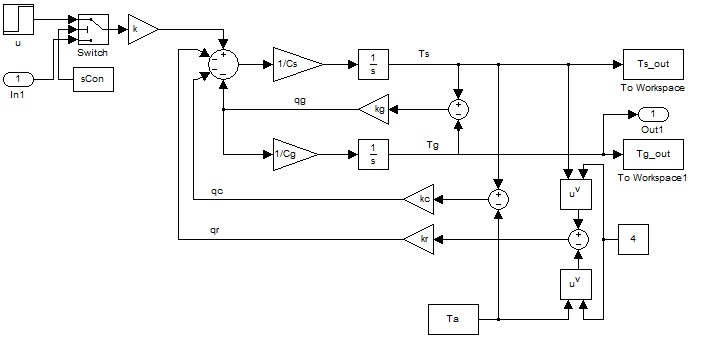

                                                                                                             Figure 1: Simulink block diagram of the model

**Problem 2** Implement a model of the system in the Simulink environment, and use the following numerical values for the model parameters


$$k_c = 0.85 \,W/^{\circ}C \\ k_g = 1.2 \,W/^{\circ}C \\ k_r = 7.8\cdot 10^{-10} \,W/K^4 \\ C_s = 75 \,J/^{\circ}C \\ C_g = 800 \,J/^{\circ}C \\ k = 100 \,W/V$$


The control signal $u$ can assume values in the interval $0-10\,V$.

**Note that you must use absolute temperatures.**

Carry out simulations on the model with the initial values $u_0 = 5\,V$, $T_{si} = 200^{\circ}C$, $T_{gi} = 25^{\circ}C$ and $T_a = 25^{\circ}C$. Determine the stationary state by simulation until all variables have assumed constant values.

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector.

**Solution**

**Simulink model**

A Simulink model of the system can be seen on figure 1, where the given data has been used. Remember to insert the initial temperature values in the integrators and set the priority of the integrator.

The stationary state is found by simulating until all variables have assumed constant values.

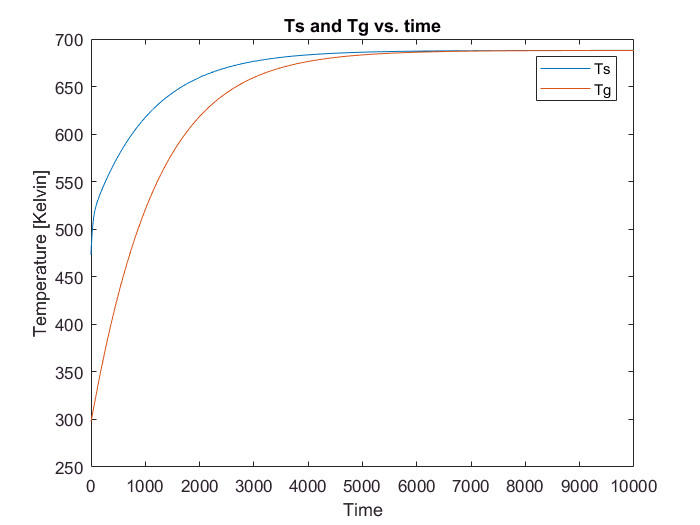


%The constants...
kc = 0.85; %Watt/deg.C
kg = 1.2;  %Watt/deg.C
kr = 7.8e-10; %Watt/K^4
Cs = 75;   %Joule/deg.C
Cg = 800;  %Joule/deg.C
k  = 100;  %Watt/volt
Ta = 298.15; %K
u0 = 5; %V
 
 % u0 is set to the constant value of 5 volt.
 % Ta is set to the constant value of 298.15 K.
 % Tsi is set to 473.15 K in the integrator initial condition 
 % Tgi is set to 298.15 K in the integrator initial condition 
 
 % After around 8000 seconds the temperature has stabilised. Tg becomes 688
 % K and Ts becomes 688 K... they are end up having the same value... wauw.
 
 sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 sim('Q8')
 
 figure
 plot(Ts_out.time,Ts_out.signals.values,'b' ,Ts_out.time, Tg_out.signals.values,'r')
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');

                               Figure 2: Steady state response of the system

As seen on figure 2 the values stabilizes around 688 Kelvin corresponding to 414.85 degrees Celsius. The settling time is around 5500 time units. If you insert these stationary values along with the initial data in equation (15) then you get an input of $u = 5.06$ which is very close to the given input. Higher accuracy may be gained by simulating over a longer period.

**Problem 3**  Linearize the nonlinear Simulink model applying the Matlab function `linmod`. Use the function as follows

`[A,B,C,D] = linmod('modelname',x0,u0)`

where $x_0$ and $u_0$ are the stationary states and inputs.

Compare the result with that from the manual linearization from question "c'' in the Problem 2.10.

Find the eigenvalues of the $\mathbf{A}$ matrix by using the Matlab function `eig()`. Repeat the linearization for $u_0 = 2\,V$ and $u_0 = 8\,V$; $T_a = 10^{\circ}C$ and  $T_a = 35^{\circ}C$, and note

how the linear model changes with the stationary state.

Remove the radiation effect (set $k_r = 0$) and repeat the linearization for different values $u_0$.

**Solution**

**Linearization with Matlab**

When using the Matlab command `linmod` on the Simulink model the following matrices are obtained


$$A = \pmatrix{ -0.0317 \ 0.0160 \cr 0.0015 \ -0.0015}\\
B = \pmatrix {1.333 \cr 0}\\ 
C = \pmatrix {1 \ 0}  \\
D = \pmatrix {0} $$


If we insert the values for the constants in the matrices in Section 1.3 we get the same values as in the matrices numerically calculated in Matlab.

%First get initial state and then use the linmod command.
 sCon = 0; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 x=Simulink.BlockDiagram.getInitialState('Q8');
 [A,B,C,D]=linmod('Q8',x,u0)

A =      -0.03174        0.016
       0.0015      -0.0015


B =        1.3333
            0


C =      0     1


D =      0


 
 eigenval = eig(A)

eigenval =     -0.032514
  -0.00072615


The eigenvalues of the dynamic matrix are found using `eig(A)`: $\lambda_1 = -0.0325$ and $\lambda_2 = -0.0007$. Note that both eigenvalues are in the left-half complex plane, hence the system is stable.

At $u_0=2$ V the stationary value for $T_s$ and $T_g$ is 488 K and $T_s$ will decline initially but start climbing again after around 120 time units. The settling time of the responses have increased making the system response slower than with $u_0=5$ V. At $u_0=8$ V the stationary value for $T_s$ and $T_g$ is 824 K and both responses have shorter settling times than with $u_0=5$ V. The system has become faster.

With $u_0$ back at the original 5 volts, the effect of $T_a$ is tested.

Figure 3 shows the three graphs in the same window, the topmost (blue,red) pair is at $T_a=308.15$ K, the middle is at $T_a=298.15$ K and the bottommost is at $T_a=283.15$ K. It is clear that the higher temperature the higher the stationary value, when the outside temperature is low the internal temperature will drop and vice versa.

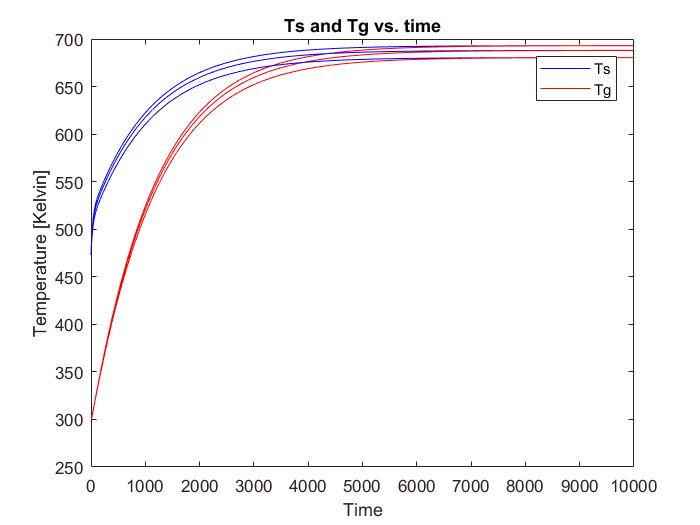

Ta1 = [308.15 298.15 283.15]; %K
u0 = 5; %V
 figure
  for i=1:3 
       Ta=Ta1(i);
 sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 sim('Q8')

     
  plot(Ts_out.time,Ts_out.signals.values,'b', Ts_out.time, Tg_out.signals.values,'r')
  hold on
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');
 end

Figure 3: The effect of changing $T_a$ among 308.15 K (top), 298.15 K (middle) and 283.15 K (lowest).

If the radiation effect is neglected $k_r=0$ then the stationary point will increase to around 880 K with a longer settling time. This is also reflected in the linearized system whose dynamics is characterized by smaller eigenvalues ($\lambda_1 = -0.0282$ and $\lambda_2 = -0.0006$). Fig.4 shows the difference between $k_r=0$ (top) and $k_r=7.8*10^{-10}$ (bottom).

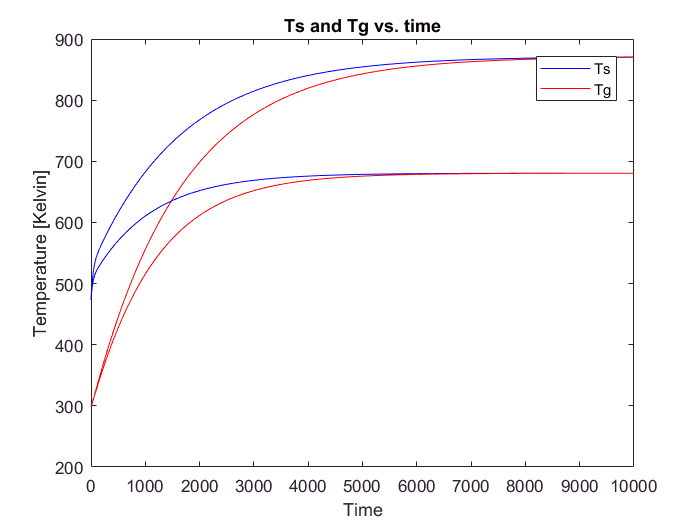

kr1 = [0 7.8e-10]; %K
u0 = 5; %V
 figure
  for i=1:2 
       kr=kr1(i);
 sCon = 1; %setting sCon to 1 take the stepinput, setting sCon to 0 take the IN.
 sim('Q8.slx')

     
  plot(Ts_out.time,Ts_out.signals.values,'b', Ts_out.time, Tg_out.signals.values,'r')
  hold on
 xlabel('Time');
 ylabel('Temperature [Kelvin]');
 title('Ts and Tg vs. time');
 legend('Ts', 'Tg');
 end

Figure4: The effect of changing $k_r $  between $0 W/K^4$ 0 (top) and $7.8 \cdot 10^{-10}$ W/$K^4$ $W/K^4$(bottom)

In absence of radiation the temperature settles in a longer time since the oven cannot dissipate the heat in excess as fast as when radiation is accounted for. The increased stationary temperature is expected because if there is less heat loss there is more heating in the oven.